R = 1e4;
C = 50e-9;
Vi = 10;
Fc = 1/(2*pi*C*R) %Frecuencia de corte

Fc = 318.3099


frecuency = logspace(0,7);

Xc = 1./(2*pi*frecuency*C);

ganancia_tesion = Xc./(sqrt(R^2+Xc.^2))

ganancia_tesion =     1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9997    0.9995    0.9990    0.9982    0.9965    0.9932    0.9870    0.9754    0.9540    0.9165    0.8550    0.7647    0.6494    0.5236    0.4045    0.3033    0.2233    0.1627    0.1178    0.0851    0.0613    0.0442    0.0318    0.0229    0.0165    0.0119    0.0085    0.0061    0.0044    0.0032    0.0023    0.0016    0.0012    0.0009    0.0006    0.0004    0.0003    0.0002    0.0002    0.0001    0.0001    0.0001    0.0000    0.0000



teta = -atand(R./Xc) %Angulo

teta =    -0.1800   -0.2501   -0.3475   -0.4829   -0.6709   -0.9322   -1.2952   -1.7994   -2.4995   -3.4710   -4.8175   -6.6792   -9.2421  -12.7401  -17.4406  -23.5824  -31.2388  -40.1240  -49.5050  -58.4268  -66.1407  -72.3432  -77.0971  -80.6380  -83.2333  -85.1192  -86.4833  -87.4675  -88.1768  -88.6877  -89.0555  -89.3202  -89.5107  -89.6479  -89.7466  -89.8176  -89.8687  -89.9055  -89.9320  -89.9511  -89.9648  -89.9747  -89.9818  -89.9869  -89.9906  -89.9932  -89.9951  -89.9965  -89.9975  -89.9982


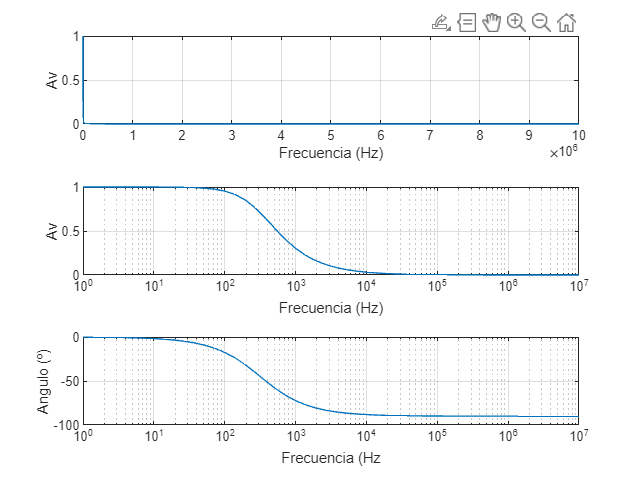


tiledlayout(3,1)

nexttile
plot(frecuency,ganancia_tesion)
grid on
ylabel('Av')
xlabel('Frecuencia (Hz)')

nexttile
semilogx(frecuency,ganancia_tesion)
grid on
ylabel('Av')
xlabel('Frecuencia (Hz)')

nexttile
semilogx(frecuency,teta)
grid on
ylabel('Angulo (º)')
xlabel('Frecuencia (Hz')